## Diseño del controlador Fuzzy

cpFIS = mamfis(...
    'NumInputs', 4, 'NumInputMFs', 5, ...
    'NumOutputs', 1, 'NumOutputMFs', 7, ...
    'AddRule', 'none');

#### Funciones de Membresia para la Posición del Pendulo

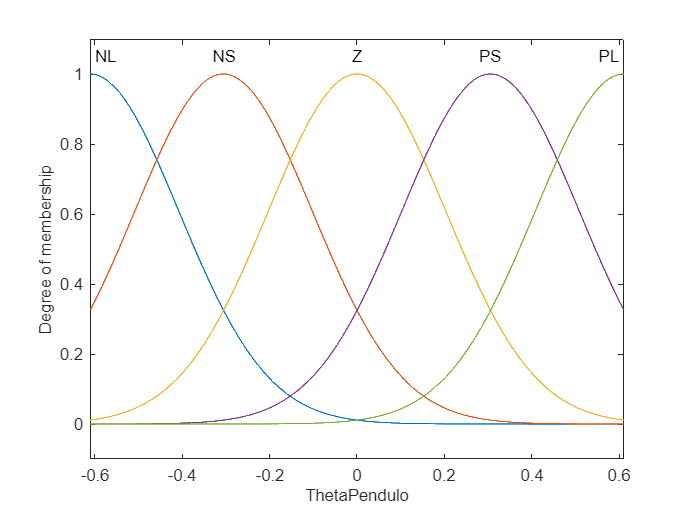

cpFIS.Inputs(1).Name = 'ThetaPendulo';
AngMax = deg2rad(35);
cpFIS.Inputs(1).Range = [-AngMax, AngMax];
centros = linspace(-AngMax, AngMax, 5);
sigma = AngMax / 3;
nombres = {'NL','NS','Z','PS','PL'};

for i = 1:5
    cpFIS.Inputs(1).MembershipFunctions(i).Name = nombres{i};
    cpFIS.Inputs(1).MembershipFunctions(i).Type = 'gaussmf';
    cpFIS.Inputs(1).MembershipFunctions(i).Parameters = [sigma centros(i)];
end
plotmf(cpFIS, 'input', 1, 1000);

#### Funciones de Membresia para la Velocidad del Pendulo

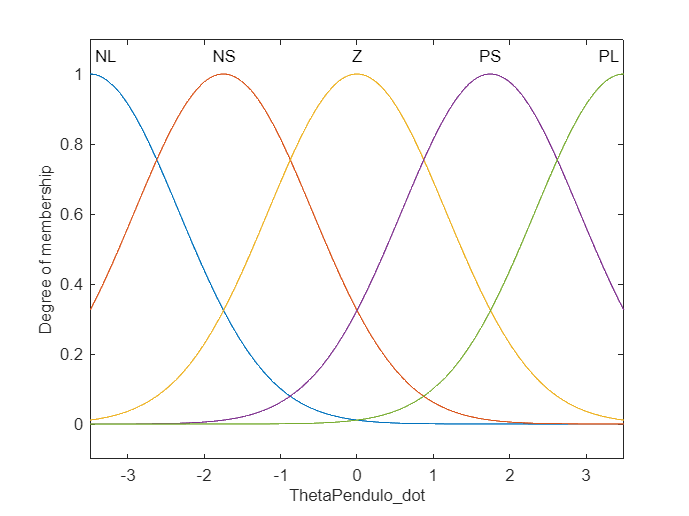

cpFIS.Inputs(2).Name = 'ThetaPendulo_dot';
VelMax = deg2rad(200);
cpFIS.Inputs(2).Range = [-VelMax, VelMax];
centros = linspace(-VelMax, VelMax, 5);
sigma = VelMax / 3;

for i = 1:5
    cpFIS.Inputs(2).MembershipFunctions(i).Name = nombres{i};
    cpFIS.Inputs(2).MembershipFunctions(i).Type = 'gaussmf';
    cpFIS.Inputs(2).MembershipFunctions(i).Parameters = [sigma centros(i)];
end
plotmf(cpFIS, 'input', 2, 1000);

#### Funciones de Membresia para la Posición del Brazo

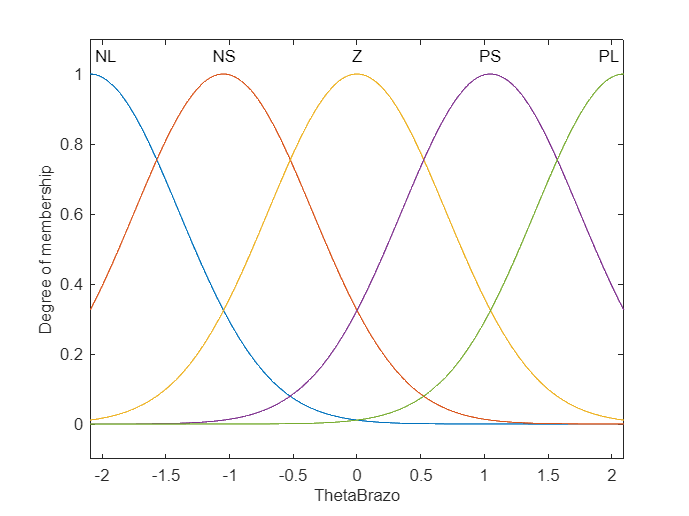

cpFIS.Inputs(3).Name = 'ThetaBrazo';
AngBrazoMax = deg2rad(120);
cpFIS.Inputs(3).Range = [-AngBrazoMax, AngBrazoMax];
centros = linspace(-AngBrazoMax, AngBrazoMax, 5);
sigma = AngBrazoMax / 3;

for i = 1:5
    cpFIS.Inputs(3).MembershipFunctions(i).Name = nombres{i};
    cpFIS.Inputs(3).MembershipFunctions(i).Type = 'gaussmf';
    cpFIS.Inputs(3).MembershipFunctions(i).Parameters = [sigma centros(i)];
end
plotmf(cpFIS, 'input', 3, 1000);

#### Funciones de Membresia para la Velocidad del Brazo

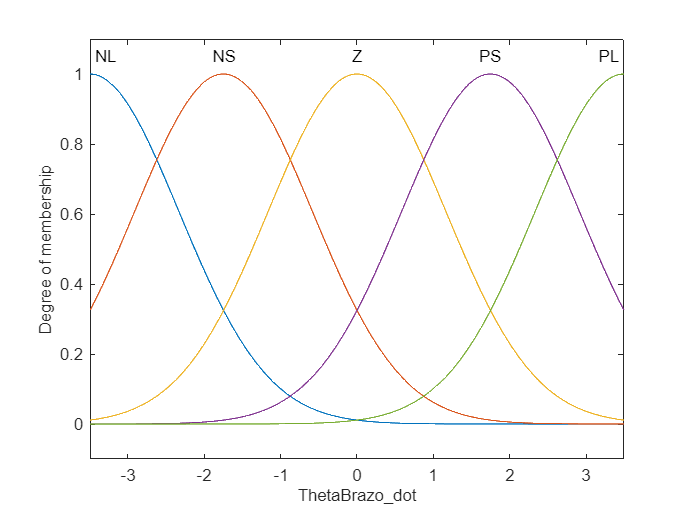

cpFIS.Inputs(4).Name = 'ThetaBrazo_dot';
VelBrazoMax = deg2rad(200);
cpFIS.Inputs(4).Range = [-VelBrazoMax, VelBrazoMax];
centros = linspace(-VelBrazoMax, VelBrazoMax, 5);
sigma = VelBrazoMax / 3;

for i = 1:5
    cpFIS.Inputs(4).MembershipFunctions(i).Name = nombres{i};
    cpFIS.Inputs(4).MembershipFunctions(i).Type = 'gaussmf';
    cpFIS.Inputs(4).MembershipFunctions(i).Parameters = [sigma centros(i)];
end
figure;
plotmf(cpFIS, 'input', 4, 1000);

### Funciones de Membresia para la Salida

#### Funciones de Membresia para la Fuerza

Se impementaron 7 fuerzas en diferentes rango para adaptar la salida respecto la mencionado en el proceso.

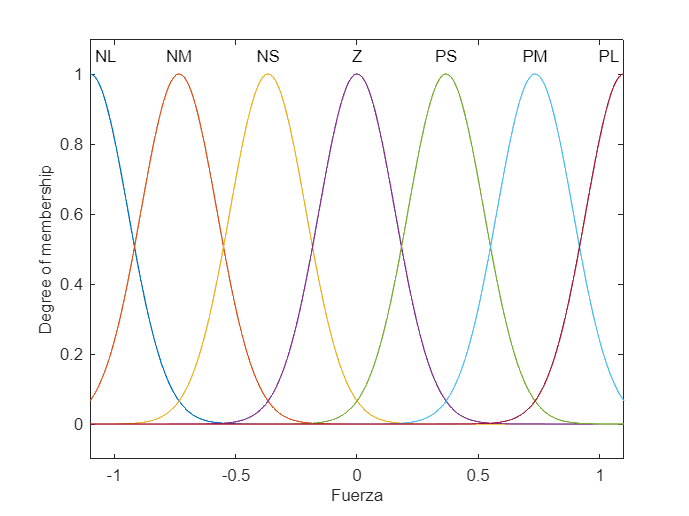

FM = 1.1; % rango máximo de salida

cpFIS.Outputs(1).Name = 'Fuerza';
cpFIS.Outputs(1).Range = [-FM, FM];

centros = linspace(-FM, FM, 7); % [-0.6 -0.4 -0.2 0 0.2 0.4 0.6]
sigma = FM / 7; % ancho estándar

nombres = {'NL', 'NM', 'NS', 'Z', 'PS', 'PM', 'PL'};

for i = 1:7
    cpFIS.Outputs(1).MembershipFunctions(i).Name = nombres{i};
    cpFIS.Outputs(1).MembershipFunctions(i).Type = 'gaussmf';
    cpFIS.Outputs(1).MembershipFunctions(i).Parameters = [sigma centros(i)];
end

figure; plotmf(cpFIS, 'output', 1, 1000);

## Reglas del controlador


rules = [
    "If ThetaPendulo is PS then Fuerza is PS"; ...
    "If ThetaPendulo is NS then Fuerza is NS"; ...
    "If ThetaPendulo is PL then Fuerza is PL"; ...
    "If ThetaPendulo is NL then Fuerza is NL"; ...
    "If ThetaPendulo is Z then Fuerza is Z";...

    "If ThetaPendulo_dot is PS then Fuerza is PS"; ...
    "If ThetaPendulo_dot is NS then Fuerza is NS"; ...
    "If ThetaPendulo_dot is PL then Fuerza is PL"; ...
    "If ThetaPendulo_dot is NL then Fuerza is NL"; ...
    "If ThetaPendulo_dot is Z then Fuerza is Z";...
    
    "If ThetaBrazo is NL then Fuerza is PS"
    "If ThetaBrazo is NS then Fuerza is PS"
    "If ThetaBrazo is PS then Fuerza is NS"
    "If ThetaBrazo is PL then Fuerza is NS"
    "If ThetaBrazo is Z then Fuerza is Z"

    "If ThetaBrazo_dot is NS then Fuerza is NS"
    "If ThetaBrazo_dot is PS then Fuerza is PS"
    "If ThetaBrazo_dot is NL then Fuerza is NS"
    "If ThetaBrazo_dot is PL then Fuerza is PS"
    "If ThetaBrazo_dot is Z then Fuerza is Z"
];

cpFIS = addRule(cpFIS, rules);

% parametros del sistema
ma=0.6; % masa brazo [kg]
mp=0.2; % masa pendulo [kg]
la=1.1600e-1; % largo del brazo [m]
lp=3.0001e-1; % largo del pendulo [m]
j0=(ma*la^2)/3; %inercia brazo [kg m^2]
g=9.8;  % gravedad [m/s^-2]
j1=(mp*lp^2)/3; % inercia pendulo [kg m^2]
T=0.05;% tiempo de muestreo

%% Control pendulo de Furuta en CoppeliaSim
% Se recomienda que sea en un archivo .m y no en un liveScript
% por la velocidad de ejecución
% A. Pantoja, Departamento de Electrónica, Universidad de Nariño
clear estados control controlmed
%clear all
close all
%% Inicialización de objeto CoppeliaSim y sincronización con planta 
vrep=remApi('remoteApi');

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


vrep.simxFinish(-1);
clientID=vrep.simxStart('127.0.0.1',19997,true,true,5000,5)

clientID = 0

r = 180*pi/180; 
re= [];
ban = 0;
ban2 = 0;
b = 0;
sws = [];
%% Parámetros del controlador Swing-up
params.mp = mp;
params.lp = lp;
params.g = g;
params.k = 2.0;
ventana = 1;
if (clientID>-1)
    disp('connected to remote API Server');
    vrep.simxSynchronous(clientID,false);
    
    % Obtención de handles
    [~,motor]=vrep.simxGetObjectHandle(clientID,'motor',vrep.simx_opmode_blocking);
    [~,sensor1]=vrep.simxGetObjectHandle(clientID,'Potenciometro',vrep.simx_opmode_blocking);
    [~,sensorvb]=vrep.simxGetObjectHandle(clientID,'rotating',vrep.simx_opmode_blocking);
    [~,sensorvp]=vrep.simxGetObjectHandle(clientID,'pendulum',vrep.simx_opmode_blocking);
    
    % Primera lectura de sensores
    [~,angb]=vrep.simxGetJointPosition(clientID,motor,vrep.simx_opmode_streaming);
    [~,angp]=vrep.simxGetJointPosition(clientID,sensor1,vrep.simx_opmode_streaming);
    [~,~,angularb]=vrep.simxGetObjectVelocity(clientID,sensorvb,vrep.simx_opmode_streaming);
    [~,~,angularp]=vrep.simxGetObjectVelocity(clientID,sensorvp,vrep.simx_opmode_streaming);
    [~,torqm]=vrep.simxGetJointForce(clientID,motor,vrep.simx_opmode_streaming);
    
    vrep.simxPauseSimulation(clientID,vrep.simx_opmode_oneshot);
    pause(2);
    
    % Inicialización de variables   
    Tsim=80;
    Ts=0.1;
    Ns=round(Tsim/Ts);
    e_ant=0;
    int_err=0;
    
    %% Main Control Cycle
    vrep.simxStartSimulation(clientID,vrep.simx_opmode_oneshot);
    
    for i=1:Ns
        tic
        
        % Lectura de estados
        [~,angb]=vrep.simxGetJointPosition(clientID,motor,vrep.simx_opmode_buffer); 
        angb = angb-floor(angb/(2*pi))*2*pi;
        
        [~,angp]=vrep.simxGetJointPosition(clientID,sensor1,vrep.simx_opmode_buffer);
        [~,~,angularb]=vrep.simxGetObjectVelocity(clientID,sensorvb,vrep.simx_opmode_buffer);
        [~,~,angularp]=vrep.simxGetObjectVelocity(clientID,sensorvp,vrep.simx_opmode_buffer);
        [~,torqm]=vrep.simxGetJointForce(clientID,motor,vrep.simx_opmode_buffer);
        
        angb = angb - floor(angb/(2*pi))*2*pi;
        
        % ... lecturas de otros sensores ...
        
        % Construir vector de estado con validación
        x = [angb; angularb(3); angp; angularp(1)];
        x = double(round(x, 4));
        % Verificar finitud y valores reales
        if any(~isfinite(x)) || ~isreal(x)
            warning('Valores no finitos o complejos en sensores! Usando último estado válido.');
            x = x_last_valid; % Usar último estado bueno
        else
            x_last_valid = x; % Actualizar último estado válido
        end
        % Estados medidos
        e_act = r - angb;
        y = x(1);
        re(i) = r;   
        x_current = x;
        
        hp(i) = abs(angp-floor(angp/(2*pi))*2*pi);
        
        % Lógica de control
        if abs(angp-floor(angp/(2*pi))*2*pi) < deg2rad(25) || abs(angp-floor(angp/(2*pi))*2*pi) > deg2rad(335) && abs(angularp(1)) < deg2rad(205)
            if ban == 0
                r = double(round(angb, 4));
                ban = 1;
                ki = 1;
            end
            ki = ki + 1;
            if ki == 60
                ban2 = 1;
            end
            %u_c = evalfis(cpFIS, [1.5*(x(3)), 0.9*x(4), 0.03*(r-x(1)), 0.05*x(2)]);
            u_c = evalfis(cpFIS, [1.5*(x(3)), 0.9*x(4), 0.03*((r-deg2rad(4.886))-x(1)), 0.05*x(2)]);
            % if ki > 5
            %     f = [control(i-ventana:i-1)';u_c];
            %     u_c = median(f);
            % end
            sw = 1;
            
        else
            ban = 0;
            ban2 = 0;

            u_c = 0.7*swing_up_energy_controller(x, params);
            int_err = 0;
            sw = 0;
        end
        
        % Saturación de control
        u_c = max(-1, min(1, u_c));
        umpc = u_c; % Guardar para próxima iteración
        
        % Aplicación de torque
        if u_c > 0
            vel = 99; 
            torqap = u_c;
        else
            vel = -99; 
            torqap = -u_c;
        end

        vrep.simxSetJointForce(clientID,motor,torqap,vrep.simx_opmode_blocking);
        vrep.simxSetJointTargetVelocity(clientID,motor,vel,vrep.simx_opmode_blocking);
        % control_suavizado = movmean(control, ventana);
        % u_c = control_suavizado;
        % Almacenamiento
        sws(i) = sw;
        e_ant = e_act;
        control(i) = u_c;
        controlmed(i) = torqm;
        estados(i,:) = x;
        
        % Cambio de referencia
        if ban2 == 1
            if i == round(30/Ts)
                r = 140*pi/180;
            elseif i == round(40/Ts)
                r = 120*pi/180;
            elseif i == round(60/Ts)
                r = 150*pi/180;
            end
        end
        
        elapsed = toc;
        pause(max(Ts - elapsed, 0));
    end 
    
    vrep.simxStopSimulation(clientID,vrep.simx_opmode_blocking);
    vrep.simxFinish(-1);
end

connected to remote API Server


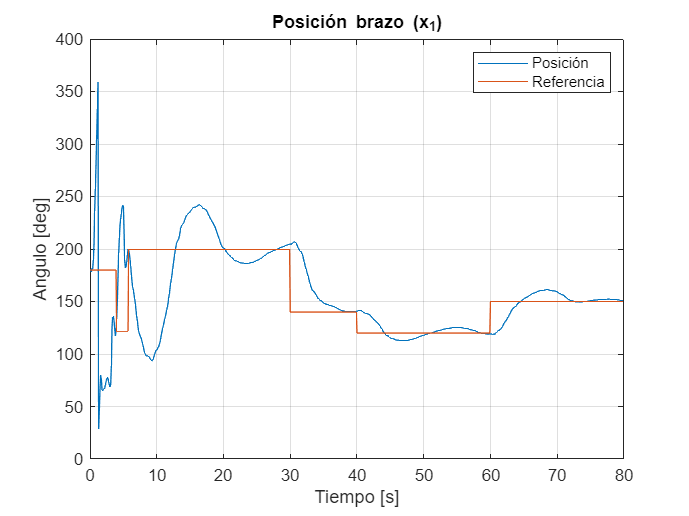

vrep.delete();

Ns = length(estados(:,1));
re = re(1:end-1);
%% Gráficas
tdisc = 0:Ts:Ns*Ts-Ts;
% re = [re, re];
if length(re) == length(tdisc)-1
    re = [re,re(end)];
end
figure;
plot(tdisc,estados(:,1)*180/pi);
hold on 
plot(tdisc, re*180/pi);
xlabel('Tiempo [s]');
ylabel('Angulo [deg]');
title('Posición brazo (x_1)');
legend('Posición', 'Referencia');
grid on;

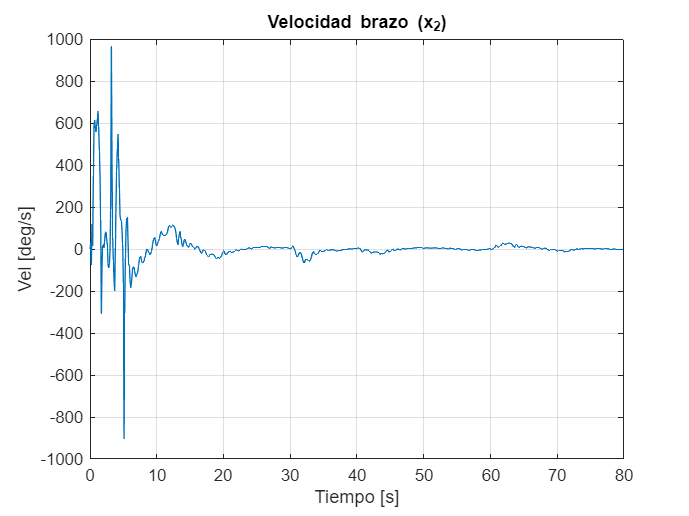


figure;
plot(tdisc,estados(:,2)*180/pi);
xlabel('Tiempo [s]');
ylabel('Vel [deg/s]');
title('Velocidad brazo (x_2)');
grid on;

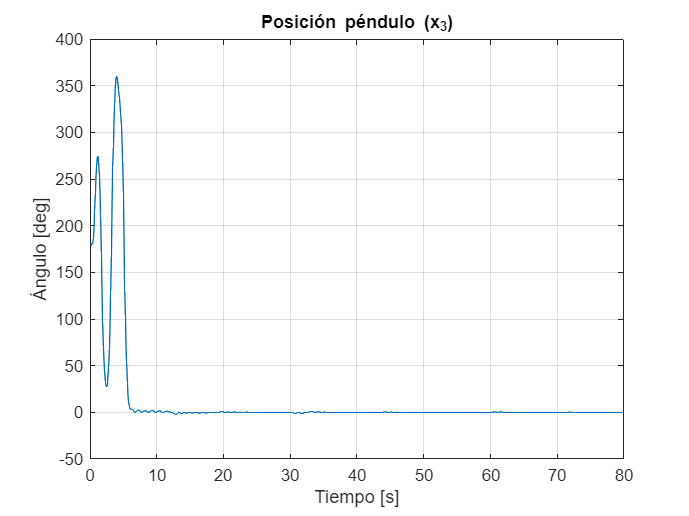


figure;
plot(tdisc,estados(:,3)*180/pi);
xlabel('Tiempo [s]');
ylabel('Ángulo [deg]');
title('Posición péndulo (x_3)');
grid on;

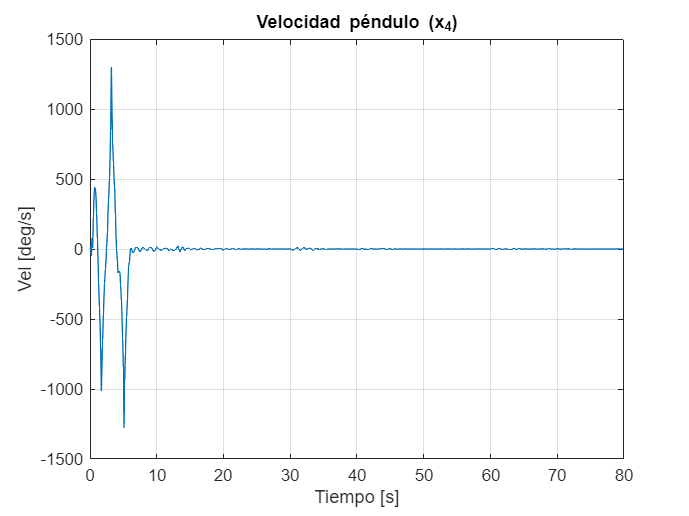


figure;
plot(tdisc,estados(:,4)*180/pi);
xlabel('Tiempo [s]');
ylabel('Vel [deg/s]');
title('Velocidad péndulo (x_4)');
grid on;

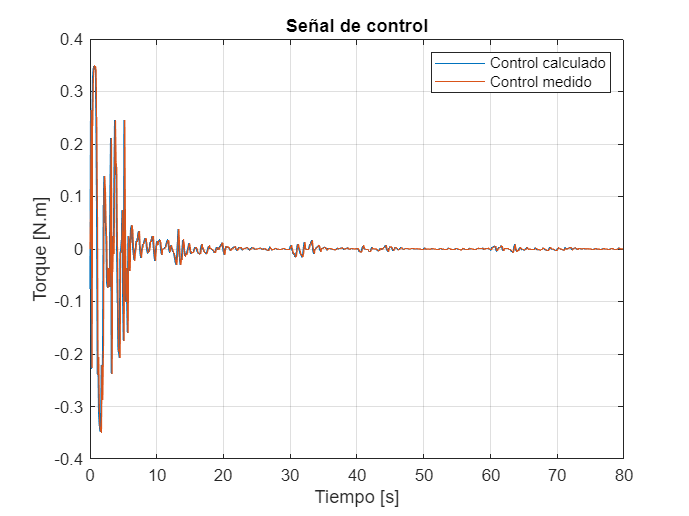

figure;
plot(tdisc,control);
hold on;
plot(tdisc,-controlmed);
xlabel('Tiempo [s]');
ylabel('Torque [N.m]');
title('Señal de control');
legend('Control calculado', 'Control medido');
grid on;